num=[0.5]

num = 0.5000

den=[1 3 4 2]

den =      1     3     4     2


G1=tf(num,den)%ordenn 3 tipo 0


G1 =
 
           0.5
  ---------------------
  s^3 + 3 s^2 + 4 s + 2
 
Continuous-time transfer function.


**PID DISCRETO**

Discretización de la planta

ts=4.3

ts = 4.3000

T=ts/70

T = 0.0614

sysd=c2d(G1,T,'zoh')


sysd =
 
  1.844e-05 z^2 + 7.045e-05 z + 1.682e-05
  ---------------------------------------
     z^3 - 2.818 z^2 + 2.65 z - 0.8317
 
Sample time: 0.061429 seconds
Discrete-time transfer function.


numZ=sysd.Numerator{1}

numZ = 1.0e-04 *

         0    0.1844    0.7045    0.1682


denZ=sysd.Denominator{1}

denZ =     1.0000   -2.8177    2.6498   -0.8317


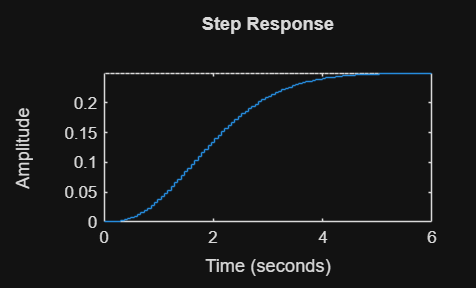

zpk(sysd);
step(sysd);

Condiciones deseadas

zita=0.7%%%% *

zita = 0.7000

ts=4.3

ts = 4.3000

Tmd=ts/70

Tmd = 0.0614

wn=4.6/(ts*zita)

wn = 1.5282

ws=2*pi/Tmd

ws = 102.2844

wd=wn*sqrt(1-zita^2)

wd = 1.0914

wd8=8*wd

wd8 = 8.7310

zpdmag=exp(-Tmd*zita*wn)

zpdmag = 0.9364

zpdang=radtodeg(Tmd*wd)

zpdang = 3.8412

[num_cd3,den_cd3]=tfdata(sysd,'v')

num_cd3 = 1.0e-04 *

         0    0.1844    0.7045    0.1682


den_cd3 =     1.0000   -2.8177    2.6498   -0.8317


syms q0 q1 q2 q3 s0 s1 z

Polinomio caracteristico

pc=(z^2-s0*z-s1)*(z-1)*(z^3+den_cd3(2)*z^2+den_cd3(3)*z+den_cd3(4))+(z^2*num_cd3(2)+ num_cd3(3)*z+num_cd3(4))*(q0*z^3+q1*z^2+q2*z+q3);
pcz=fliplr(coeffs(pc,z))

$$pcz = \left(\begin{array}{ccccccc} 1 & \frac{170121997562003\,q_{0}}{9223372036854775808}-s_{0}-\frac{2149181252984395}{562949953421312} & \frac{2599082957956607\,q_{0}}{36893488147419103232}+\frac{170121997562003\,q_{1}}{9223372036854775808}+\frac{2149181252984395\,s_{0}}{562949953421312}-s_{1}+\frac{6155910245255261}{1125899906842624} & \frac{2482345759415119\,q_{0}}{147573952589676412928}+\frac{2599082957956607\,q_{1}}{36893488147419103232}+\frac{170121997562003\,q_{2}}{9223372036854775808}-\frac{6155910245255261\,s_{0}}{1125899906842624}+\frac{2149181252984395\,s_{1}}{562949953421312}-\frac{31358852052347907}{9007199254740992} & \frac{2482345759415119\,q_{1}}{147573952589676412928}+\frac{2599082957956607\,q_{2}}{36893488147419103232}+\frac{170121997562003\,q_{3}}{9223372036854775808}+\frac{31358852052347907\,s_{0}}{9007199254740992}-\frac{6155910245255261\,s_{1}}{1125899906842624}+\frac{7491270883315147}{9007199254740992} & \frac{2482345759415119\,q_{2}}{147573952589676412928}+\frac{2599082957956607\,q_{3}}{36893488147419103232}-\frac{7491270883315147\,s_{0}}{9007199254740992}+\frac{31358852052347907\,s_{1}}{9007199254740992} & \frac{2482345759415119\,q_{3}}{147573952589676412928}-\frac{7491270883315147\,s_{1}}{9007199254740992} \end{array}\right)$$

Polinomio deseado

pd=conv([1 -2*zpdmag*cosd(zpdang) zpdmag^2],[1 0.05])

pd =     1.0000   -1.8186    0.7834    0.0438


pd=conv(pd,[1 0.05])

pd =     1.0000   -1.7686    0.6925    0.0830    0.0022


pd=conv(pd,[1 0.05])

pd =     1.0000   -1.7186    0.6041    0.1176    0.0063    0.0001


pd=conv(pd,[1 0.05])

pd =     1.0000   -1.6686    0.5181    0.1478    0.0122    0.0004    0.0000


Constantes del control

[s0,s1, q0, q1, q2,q3]=solve(pd==pcz,[s0,s1, q0, q1,q2,q3]);
s0g1=double(vpa(s0,5))

s0g1 = -1.5824

s1g1=double(vpa(s1,5))

s1g1 = -0.3407

q0g1=double(vpa(q0,5))

q0g1 = 3.0724e+04

q1g1=double(vpa(q1,5))

q1g1 = -7.6622e+04

q2g1=double(vpa(q2,5))

q2g1 = 6.2837e+04

q3g1=double(vpa(q3,5))

q3g1 = -1.6844e+04